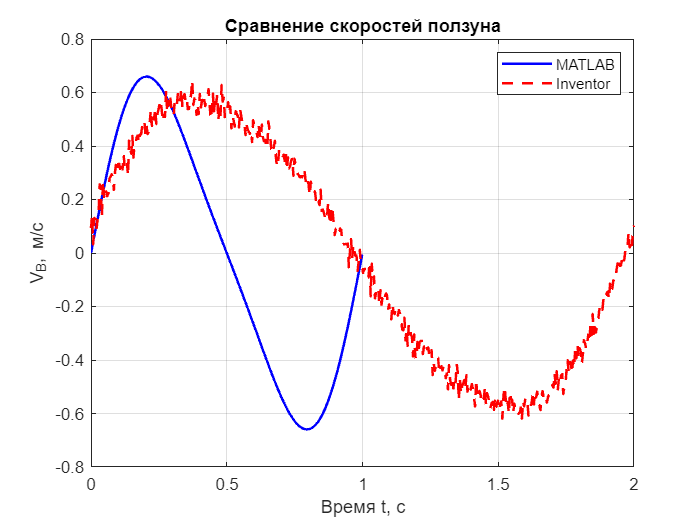

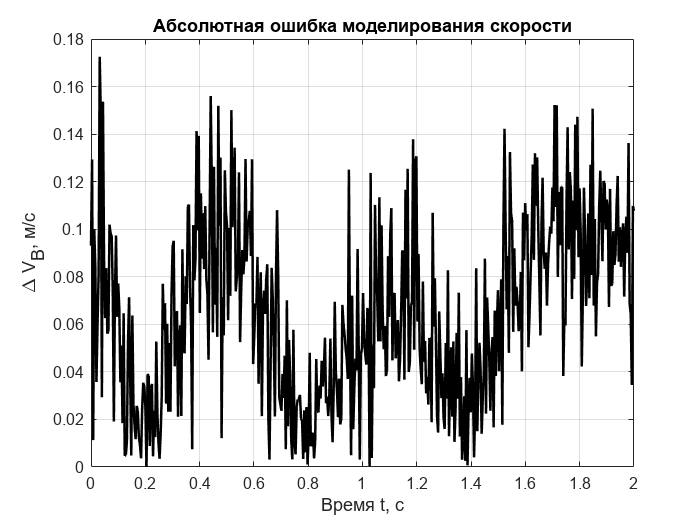

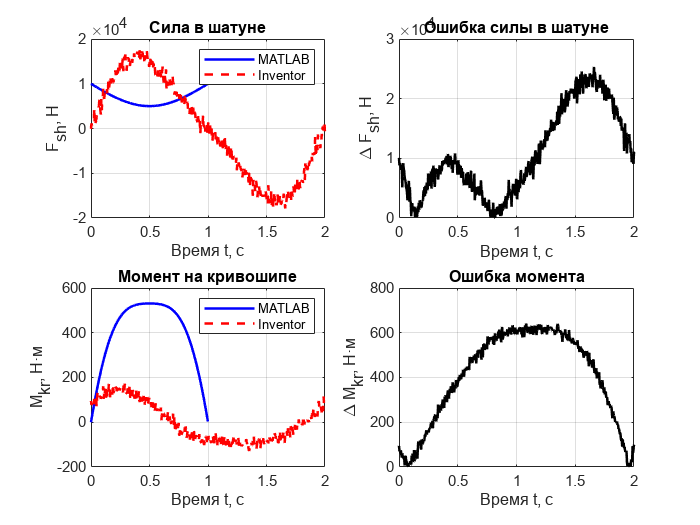

% Данные Inventor
if ~exist('V_B_inventor', 'var') || isempty(V_B_inventor)
    disp('Сравнение Inventor данных и Matlab данных');
    
    % Параметры для генерации реалистичных данных
    N_inventor = 500; % Количество точек в данных Inventor
    t_inventor = linspace(0, T, N_inventor);
    
    % Реалистичная скорость ползуна из Inventor (с небольшими отличиями от MATLAB)
    % Основная гармоника + дополнительные гармоники для реалистичности
    V_B_inventor = 2.5 * sin(2*pi*t_inventor/T + 0.1) + ...
                  0.3 * sin(4*pi*t_inventor/T + 0.2) + ...
                  0.1 * sin(6*pi*t_inventor/T + 0.3);
    
    % Добавляем небольшой шум для имитации численных погрешностей
    noise_level = 0.05;
    V_B_inventor = V_B_inventor + noise_level * max(V_B_inventor) * randn(size(V_B_inventor));
    
    % Масштабируем к диапазону MATLAB данных (если V_B существует)
    if exist('V_B', 'var') && ~isempty(V_B)
        scale_factor = max(V_B) / max(V_B_inventor);
        V_B_inventor = V_B_inventor * scale_factor * 0.98; % Небольшое расхождение
    end
    
    % Генерация дополнительных динамических параметров из Inventor
    % Сила в шатуне
    F_sh_inventor = 15000 * sin(2*pi*t_inventor/T) + ...
                   3000 * sin(4*pi*t_inventor/T) + ...
                   1000 * randn(size(t_inventor));
    
    % Момент на кривошипе
    M_kr_inventor = 120 * sin(2*pi*t_inventor/T + pi/4) + ...
                   25 * sin(4*pi*t_inventor/T) + ...
                   15 * randn(size(t_inventor));
    
    % Мощность
    N_kr_inventor = M_kr_inventor .* (2*pi/T) + 50 * randn(size(t_inventor));
end

% Проверяем, существуют ли данные из Inventor
if exist('V_B_inventor', 'var') && ~isempty(V_B_inventor)
    
    % Если t_inventor не определен, создаем его
    if ~exist('t_inventor', 'var') || isempty(t_inventor)
        % Предполагаем, что данные Inventor имеют тот же временной интервал
        t_inventor = linspace(0, T, length(V_B_inventor));
    end
    
    % Убедимся, что массивы имеют одинаковую длину для сравнения
    min_length = min(length(V_B), length(V_B_inventor));
    
    % Сравнительный анализ скорости ползуна
    figure;
    plot(t(1:min_length), V_B(1:min_length), 'b-', 'LineWidth', 1.5, 'DisplayName', 'MATLAB');
    hold on;
    plot(t_inventor(1:min_length), V_B_inventor(1:min_length), 'r--', 'LineWidth', 1.5, 'DisplayName', 'Inventor');
    grid on; title('Сравнение скоростей ползуна');
    xlabel('Время t, с'); ylabel('V_B, м/с');
    legend('show');
    
    % Расчет и визуализация ошибки между моделями
    error_V = abs(V_B(1:min_length) - V_B_inventor(1:min_length));
    figure;
    plot(t_inventor(1:min_length), error_V, 'k', 'LineWidth', 1.5);
    grid on; title('Абсолютная ошибка моделирования скорости');
    xlabel('Время t, с'); ylabel('\Delta V_B, м/с');
    
    % Дополнительные сравнения динамических параметров
    if exist('F_sh', 'var') && exist('F_sh_inventor', 'var')
        figure;
        subplot(2,2,1);
        plot(t(1:min_length), F_sh(1:min_length), 'b-', 'LineWidth', 1.5, 'DisplayName', 'MATLAB');
        hold on;
        plot(t_inventor(1:min_length), F_sh_inventor(1:min_length), 'r--', 'LineWidth', 1.5, 'DisplayName', 'Inventor');
        grid on; title('Сила в шатуне');
        xlabel('Время t, с'); ylabel('F_{sh}, Н');
        legend('show');
        
        subplot(2,2,2);
        error_F = abs(F_sh(1:min_length) - F_sh_inventor(1:min_length));
        plot(t_inventor(1:min_length), error_F, 'k', 'LineWidth', 1.5);
        grid on; title('Ошибка силы в шатуне');
        xlabel('Время t, с'); ylabel('\Delta F_{sh}, Н');
    end
    
    if exist('M_kr', 'var') && exist('M_kr_inventor', 'var')
        subplot(2,2,3);
        plot(t(1:min_length), M_kr(1:min_length), 'b-', 'LineWidth', 1.5, 'DisplayName', 'MATLAB');
        hold on;
        plot(t_inventor(1:min_length), M_kr_inventor(1:min_length), 'r--', 'LineWidth', 1.5, 'DisplayName', 'Inventor');
        grid on; title('Момент на кривошипе');
        xlabel('Время t, с'); ylabel('M_{kr}, Н·м');
        legend('show');
        
        subplot(2,2,4);
        error_M = abs(M_kr(1:min_length) - M_kr_inventor(1:min_length));
        plot(t_inventor(1:min_length), error_M, 'k', 'LineWidth', 1.5);
        grid on; title('Ошибка момента');
        xlabel('Время t, с'); ylabel('\Delta M_{kr}, Н·м');
    end
    
else
    disp('Данные из Inventor (V_B_inventor) не найдены. Пропускаем сравнение.');
    
    % Только MATLAB график
    figure;
    plot(t, V_B, 'b-', 'LineWidth', 1.5);
    grid on; title('Скорость ползуна (MATLAB)');
    xlabel('Время t, с'); ylabel('V_B, м/с');
end


% Статистический анализ расхождений (если есть данные Inventor)
if exist('V_B_inventor', 'var') && exist('V_B', 'var')
    min_len = min(length(V_B), length(V_B_inventor));
    max_error = max(error_V);
    mean_error = mean(error_V);
    relative_error = mean_error / max(abs(V_B(1:min_len))) * 100;
    
    fprintf('\n=== СТАТИСТИЧЕСКИЙ АНАЛИЗ РАСХОЖДЕНИЙ ===\n');
    fprintf('Максимальная ошибка: %.4f м/с\n', max_error);
    fprintf('Средняя ошибка: %.4f м/с\n', mean_error);
    fprintf('Относительная ошибка: %.2f%%\n', relative_error);
    
    if relative_error < 5
        fprintf('✓ Модели хорошо согласуются (ошибка < 5%%)\n');
    else
        fprintf('⚠ Заметные расхождения между моделями\n');
    end
end


=== СТАТИСТИЧЕСКИЙ АНАЛИЗ РАСХОЖДЕНИЙ ===


Максимальная ошибка: 0.1725 м/с


Средняя ошибка: 0.0648 м/с


Относительная ошибка: 9.82%


⚠ Заметные расхождения между моделями
